# InterfaceLiveScript

Teste das função NEuler e NRK2 com exemplo da sebenta de AM2

Arménio Correia | armenioc@isec.pt

aula04T | 05/03/2024 »  aula05P | 14/03/2024

Alterações feitas por :

 Tiago Oliveira | a2022137225@isec.pt

 Pedro Sherring  | a2020126540@isec.pt

 Pedro Martins  | a2021118351@isec.pt

 26/04/2024 

ans = 21×8 table
     t        Exata         Euler         EulerM         RK2           RK4        ODE45       Heun   
    ____    __________    __________    __________    __________    __________    _____    __________

       1             2             2             2             2             2       1              2
    1.45        26.126        11.938        24.402        27.088        26.115    1.45          25.56
     1.9        129.65        52.176        114.57        134.54        129.59     1.9         126.55
    2.35         545.4        210.15        466.99        565.61        545.14    2.35         531.95
     2.8        2174.9         823.5          1832        2254.1        2173.8     2.8         212

ans = 21×6 table
    erroEuler     erroEulerM     erroRK2       erroRK4      erroODE45      erroHeun 
    __________    __________    __________    __________    __________    __________

             0             0             0             0             1             0
        14.187        1.7238        0.9624      0.010393        24.676       0.56537
        77.476        15.082        4.8912      0.059448        127.75         3.101
        335.26        78.418        20.203       0.26447        543.05        13.457
        1351.4        342.84        79.233        1.0828        2172.1        54.338
        5305.6        1396.3        306.44        4.2868        8497.6        213.54
         20613        5514.6        1181.4        16.727         32962        830.09
         7974

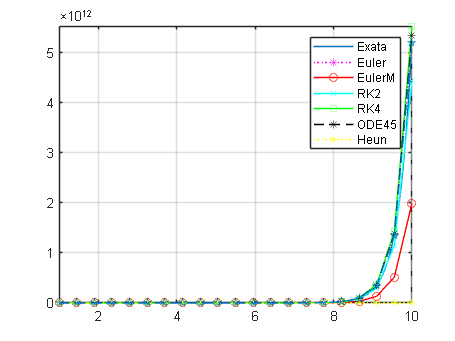

clear
syms y(t)

%% Dados do PVI 
% y'=f(t,y) t=[a,b] y(a)=y0

%help function_handle
strF = "y+exp(3*t)";
f =@(t,y) eval(vectorize(strF));
try
    fTeste = f(t,y);
    %f(0,1)
catch
    disp(upper("Introduza uma função em t e y"))
end
a = 1;
b = 10;
if ~(isscalar(b) && b>a)
    disp("Introduza um b > a")
end
n = 20;
y0 = 2;

try
[~,yEuler] = NEuler(f,a,b,n,y0);
[~,yEulerM] = NEuler_melhorado(f,a,b,n,y0);
[~,yRK2] = NRK2(f,a,b,n,y0);
[~,yRK4] = NRK4(f,a,b,n,y0);
yODE45 = ODE45(f,a,b,n,y0);
[~,yNODE23] = NODE23(f,a,b,n,y0);

sExata = dsolve(diff(y,t)==f(t,y),y(a)==y0);
fplot(sExata,[a,b])

g = @(t) eval(vectorize(char(sExata)));

h = (b-a)/n;
t = a:h:b;
yExata = g(t);

erroEuler = abs(yExata-yEuler);
erroEulerM = abs(yExata-yEulerM);
erroRK2 = abs(yExata-yRK2);
erroRK4 = abs(yExata-yRK4);
erroODE45 = abs(yExata-yODE45);
erroNODE23 = abs(yExata-yNODE23);

tabela = [t.',yExata.',yEuler.',yEulerM.',yRK2.',yRK4.',yODE45.',yNODE23.'];
array2table(tabela,"VariableNames",{'t','Exata','Euler','EulerM','RK2','RK4','ODE45','NODE23'})
    
tabelaErr = [erroEuler.',erroEulerM.',erroRK2.',erroRK4.',erroODE45.',erroNODE23.'];
array2table(tabelaErr,"VariableNames",{'erroEuler','erroEulerM','erroRK2','erroRK4','erroODE45','erroNODE23'})
    
hold on
plot(t,yExata,"m*:")
plot(t,yEuler,"-ro")
plot(t,yEulerM,"cx-")
plot(t,yRK2,"-gs")
plot(t,yRK4,"k*--")
plot(t,yODE45,"y*:")
plot(t,yNODE23,"p--")

hold off
grid on
legend('Exata','Euler','EulerM','RK2','RK4','ODE45','NODE23')

catch Me
    disp(upper("Ocorreu um erro na chamada das funções e/ou display de resultados"))
    errordlg("Ocorreu um erro","ERRO","modal")
    errordlg(Me.message,"ERRO","modal")
end